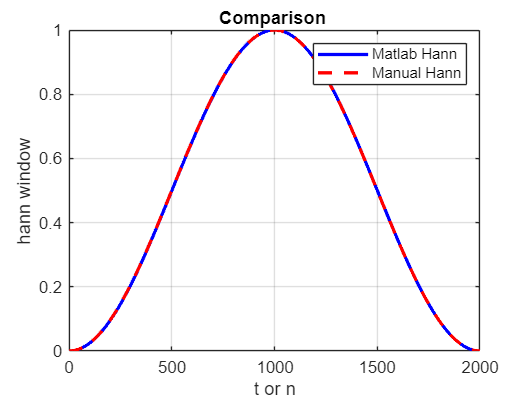

N=2000;
frames=buffer(S,N,N/2);

%constructed manualy
t=1:1:2000;
hann_win = sin(pi * t / N).^2;

win=hann(N);


figure;  
plot(t,win, 'b-',t,hann_win, 'r--', 'LineWidth', 2);  
xlabel('t or n');  
ylabel('hann window');  
title('Comparison ');  
legend('Matlab Hann', 'Manual Hann');  
grid on;  

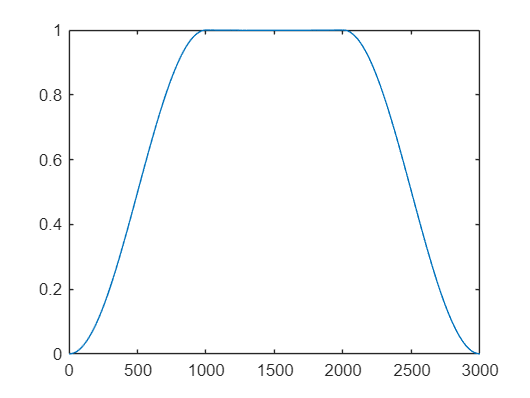


shifted_window = [zeros(N/2,1) ; win];
win2 = [win; zeros(N/2,1)];
added = win2 + shifted_window;

figure;
plot(added)


win_frames =frames .* win;
win_frames_downed = win_frames(:,1:2:end);

num_frames_downed =size(win_frames_downed, 2);

S_4 = zeros(N/2 * num_frames_downed, 1);
for i = 1:num_frames_downed
    s_idx= (i-1) * N/2+ 1;
    end_idx = i *N/2;
    S_4(s_idx:end_idx) = win_frames_downed(1:N/2,i);
end

sound(S_4,Fs)

